# Aceleración mediolateral carrera

Calcula la aceleración medio-lateral durante foot-strike en carrera.

## Syntax

`[acc_medio_lateral_footstrike, acc_medio_lateral_footstrike_moda] = aceleracion_mediolateral_carrera(IC, acc_medio_lateral);`

## Description

`aceleracion_mediolateral_carrera calcula la aceleración medio-lateral en los instantes de foot-strike a partir de los índices IC y la señal de aceleración acc_medio_lateral. Devuelve un vector acc_medio_lateral_footstrike con los valores de aceleración en cada evento, normalizados en Gs (dividiendo entre 9.81), y el valor más frecuente (moda) de dicha aceleración.`

## Examples

A partir de señales y eventos detectados:

fs = 100; 
t = 0:1/fs:10;
acc_medio_lateral = 0.3*sin(2*pi*2*t) + 0.05*randn(size(t));  

Simulamos los índices del foot-strile (cada 1.2s)

IC = num2cell(round(1.2*fs:1.2*fs:length(t)));

Calculamos la aceleración medio-lateral

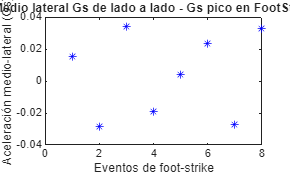

[acc_fs, acc_fs_moda] = aceleracion_mediolateral_carrera(IC, acc_medio_lateral);

Representamos el resultado gráficamente.

disp(['Moda de la aceleración medio-lateral en foot-strike: ', num2str(acc_fs_moda, '%.3f'), ' G']);

Moda de la aceleración medio-lateral en foot-strike: -0.028 G


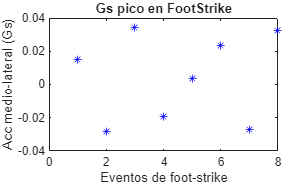


figure
plot(acc_fs, 'b*')
title('Gs pico en FootStrike')
xlabel('Eventos de foot-strike')
ylabel('Acc medio-lateral (Gs)')

Los valores se normalizan dividiendo entre 9.81 para obtener unidades en Gs.

Si los índices de IC están fuera del rango de acc_medio_lateral, la función puede generar un error.

Esta función forma parte del módulo de análisis de dinámica de carrera de la SIMUR Toolbox.